# **Big data processing: datastores + tall arrays** 

Set up execution environment

### Datastores

A datastore is an object for reading a single file or a collection of files or data. The datastore acts as a repository for collections of data that are too large to fit in memory. A datastore allows you to read and process data in smaller portions that do fit in memory. 

A datastore is useful when:

- Each file in the collection might be too large to fit in memory. A datastore allows you to read and analyze data from each file in smaller portions that do fit in memory.

- Files in the collection have arbitrary names. A datastore acts as a repository for files in one or more folders. The files are not required to have sequential names.

For more information, see [Getting Started with Datastore](https://it.mathworks.com/help/matlab/import_export/what-is-a-datastore.html).

Among the different types of datastores that you can create in MATLAB, [ImageDatastore](http://it.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html) creates an object to manage a collection of image files, where each individual image fits in memory, but the entire collection of images does not necessarily fit.

Create a [`datastore`](https://www.mathworks.com/help/matlab/ref/datastore.html) that points to the file, files, database, or hadoop/Spark cluster with the data.  

ds = datastore('airlinesmall.csv');

Replace every instance of 'NA' with a NaN in the imported data and preview the datastore.

ds.TreatAsMissing = 'NA'
preview(ds)

Not all of the variables (columns) are needed for this analysis.  Keep just the ones needed and preview.

vars = {'ArrDelay','Month','DayofMonth','DayOfWeek','AirTime','TaxiOut'};

ds =   TabularTextDatastore with properties:

                      Files: {
                             '/MATLAB/toolbox/matlab/demos/airlinesmall.csv'
                             }
                    Folders: {
                             '/MATLAB/toolbox/matlab/demos'
                             }
               FileEncoding: 'UTF-8'
   AlternateFileSystemRoots: {}
      PreserveVariableNames: false
          ReadVariableNames: true
              VariableNames: {'Year', 'Month', 'DayofMonth' ... and 26 more}
             DatetimeLocale: en_US

  Text Format Properties:
             NumHeaderLines: 0
                  Delimiter: ','
               RowDelimiter: '\r\n'
             TreatAsMissing: 'NA'
               MissingValue: NaN

  Advanced Text Format Properties:
            TextscanFormats: {'%f', '%f', '%f' ... and 26 more}
                   TextType: 'char'
         Exponen

ds.SelectedVariableNames = vars;

ans = 8×29 table
    Year    Month    DayofMonth    DayOfWeek    DepTime    CRSDepTime    ArrTime    CRSArrTime    UniqueCarrier    FlightNum    TailNum    ActualElapsedTime    CRSElapsedTime    AirTime    ArrDelay    DepDelay    Origin      Dest      Distance    TaxiIn    TaxiOut    Cancelled    CancellationCode    Diverted    CarrierDelay    WeatherDelay    NASDelay    SecurityDelay    LateAircraftDelay
    ____    _____    __________    ____

preview(ds)

If all of the data in the datastore for the variables of interest fit in memory, you can read it using the `readall` function

T = readall(ds);

Otherwise, you can read the data in smaller subsets that do fit in memory, using the `read` function. By default, the `read` function reads from a `TabularTextDatastore` 20,000 rows at a time. However, you can change this value by assigning a new value to the `ReadSize` property.

ds.ReadSize = 15000;
reset(ds)

ans = 8×6 table
    ArrDelay    Month    DayofMonth    DayOfWeek    AirTime    TaxiOut
    ________    _____    __________    _________    _______    _______

        8        10          21            3          NaN        NaN  
        8        10          26            1          NaN        NaN  
       21        10          23            5          NaN        NaN  
       13        10          23            5          NaN        NaN  
        4        10          22            4          NaN        NaN  
       59        10          28            3          NaN        NaN  
        3        10           8            4          NaN        NaN  
       11        10          10            6          NaN        NaN  


X = [];
while hasdata(ds)
      T = read(ds);
      X(end+1) = max(T.ArrDelay);
end
maxDelay = max(X)

### Tall Arrays

### 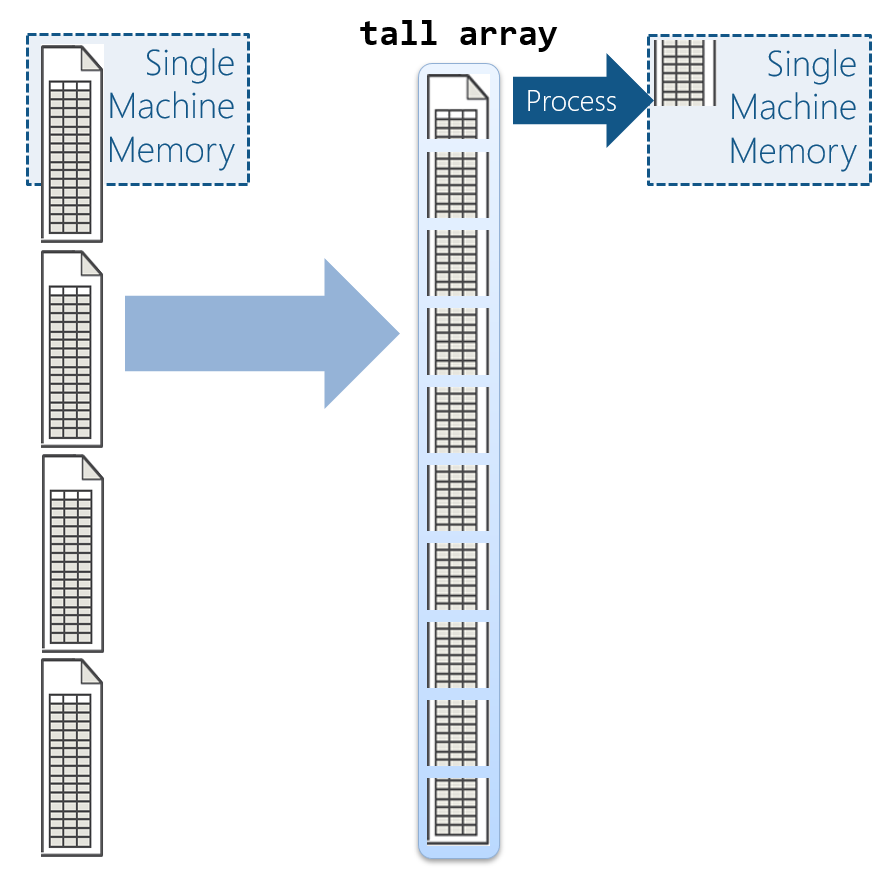

[Tall arrays](https://www.mathworks.com/help/matlab/tall-arrays.html) are used to work with large data sets that consist of many rows, perhaps so many that the entire array, or operations on the entire array, will not fit into memory.  Tall arrays simplify working with big data by handling the data management for you while minimizing reading and writing to disk.

Tall arrays wrap around datastores and treat the entire set of data as one continuous table or array. When we need to run calculations, the underlying datastore let’s us work through the array one piece at a time. However, that’s all under the hood, and when you’re using a tall array you just write normal MATLAB code. 

- Automatically breaks data up into small “chunks” that fit in memory

- Tall arrays scan through the dataset one “chunk” at a time

- Processing code for tall arrays is the same as ordinary arrays

Create a tall array from the `datastore`.

tt = tall(ds)

A tall variable can be also created from another tall variable.

a = tt.ArrDelay

**Deferred evaluation of Tall Arrays**

Unlike in-memory arrays, tall arrays typically remain unevaluated until you request that the calculations be performed using the `gather` function. This *deferred evaluation* allows you to work quickly with large data sets. When you eventually request output using `gather`, MATLAB combines the queued calculations where possible and takes the minimum number of passes through the data. The number of passes through the data greatly affects execution time, so it is recommended that you request output only when necessary.

m = mean(a,'omitnan')
s = std(a,'omitnan')
one_sigma_bounds = [m-s m m+s]

To force computation, explicitly [`gather`](https://www.mathworks.com/help/matlab/ref/gather.html) the tall variables.  Notice how it did just one pass for both mean and standard deviation.

sig1 = gather(one_sigma_bounds) 

maxDelay = 1014

Tall arrays support saving, loading and checkpointing. The [`write`](https://www.mathworks.com/help/matlab/ref/tall.write.html) function makes a copy of the data and saves the copy as a collection of files, which can consume a large amount of disk space. `write` executes all pending operations on the tall array to calculate the values prior to writing. This use of `write` is similar to `gather`, however, `write` does not bring any results into memory.

# **Distributed Arrays **

If your data is currently in the memory of your local machine, you can use the `distributed` function to distribute an existing array from the client workspace to the workers of a parallel pool. `Distributed` arrays use the combined memory of multiple workers in a parallel pool to store the elements of an array.

You can use `distributed` arrays to scale up your big data computation. Consider `distributed` arrays when you have access to a cluster, as you can combine the memory of multiple machines in your cluster.

A `distributed` array is a single variable, split over multiple workers in your parallel pool. You can work with this variable as one single entity, without having to worry about its distributed nature.

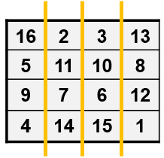

if isempty(gcp('nocreate'))

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).

tt =

  M×6 tall table

    ArrDelay    Month    DayofMonth    DayOfWeek    AirTime    TaxiOut
    ________    _____    __________    _________    _______    _______

        8        10          21            3          NaN        NaN  
        8        10          26            1          NaN        NaN  
       21        10          23            5          NaN        NaN  
       13        10          23            5          NaN        NaN  
        4        10          22            4          NaN        NaN  
       59        10          28 

    parpool('local')
end

**How to create a distributed array**

Method 1

Method 2

%% Distribute array to workers

a =

  M×1 tall double column vector

     8
     8
    21
    13
     4
    59
     3
    11
    :
    :



% Create array on client
A = reshape(1:32, 4, 8);

% Distribute the array so that each worker has 

m =

  tall double

    ?

Preview deferred. Learn more.



% selected columns only

s =

  tall

    ?

Preview deferred. Learn more.



A = distributed(A)

one_sigma_bounds =

  M×N×... tall array

    ?    ?    ?    ...
    ?    ?    ?    ...
    ?    ?    ?    ...
    :    :    :
    :    :    :

Preview deferred. Learn more.



The single program multiple data (`spmd`) construct lets you define a block of code that runs in parallel on all the workers in a parallel pool. Each worker can operate on a different data set or different portion of distributed data, and can communicate with other participating workers while performing the parallel computations.

spmd

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: 0% complete
- Pass 1 of 1: 100% complete
- Pass 1 of 1: Completed in 3.4 sec
Evaluation completed in 4.7 sec


sig1 =   -23.4572    7.1201   37.6975


    disp(getLocalPart(A))
end

A =

     1     5     9    13    17    21    25    29
     2     6    10    14    18    22    26    30
     3     7    11    15    19    23    27    31
     4     8    12    16    20    24    28    32



Lab 1: 
       1     5
       2     6
       3     7
       4     8
  
Lab 2: 
       9    13
      10    14
      11    15
      12    16
  
Lab 3: 
      17    21
      18    22
      19    23
      20    24
  
Lab 4: 
      25    29
      26    30
      27    31
      28    32
  
